# Discrete Fourier Transform

**Learning Goals**

- <LO 1>

- <LO 2>

## Introduction

The Fourier transform can be used to solve for the frequency content of an analytic function.

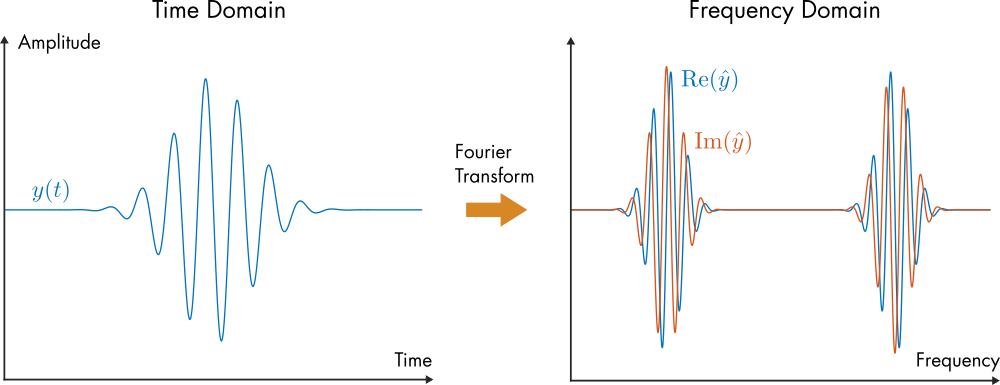

*Gaussian-modulated sinusoid in the time and frequency domains.*

However, real signals are typically discrete sequences of measured values, not analytic functions. For such a signal, the Fourier transform cannot be applied directly.

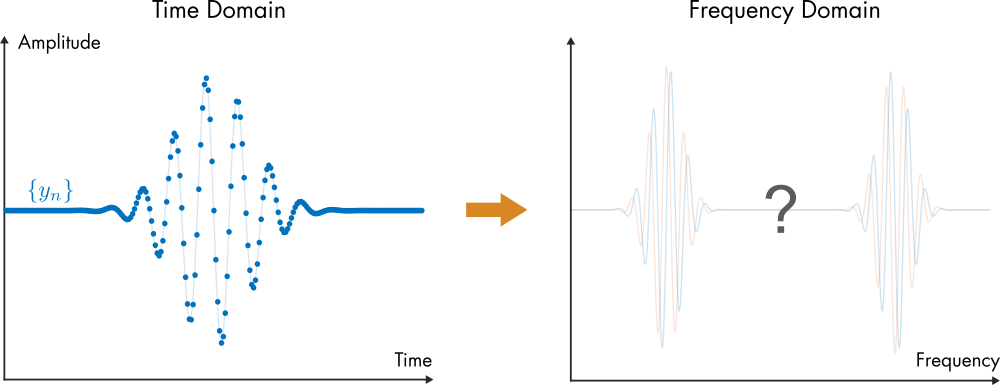

*A discrete signal *$\{ y_n \}$* sampled from an analytic function. What will it look like in the frequency domain?*

To analyze a discrete signal in the frequency domain, you can use the *Discrete Fourier Transform *(DFT). You'll often find this under a different name: the FFT (*Fast Fourier Transform*). Don't be confused, though, they're fundamentally the same. The FFT is simply an algorithm that computes the DFT, you guessed it, faster.

## Definition

The DFT is similar to the complex Fourier series and Fourier Transform. The essential difference is that it operates entirely in terms of discrete sequences, without any reference to continuous functions. The DFT is defined as


$$Y_k = \sum_{n = 0}^{N-1} y_n e^{- \frac{ 2 \pi i k n }{N }$$


The result is a sequence of $N$discrete values $\{ Y_k \}$ that represent $\{ y_n \}$ in the frequency domain. The result $\{ Y_k \}$ is analagous to the Fourier transform $\hat{y}(\omega)$, but more on that later.

## Computing the DFT

Computing the DFT using the definition requires $O(N^2)$ operations. This method is rarely used because the DFT can be computed much faster using the FFT.

### Fast Fourier Transform (FFT)

The FFT requires only $O(N \log(N))$ operations. The FFT algorithm breaks up the DFT into smaller DFTs, and then combines the results together to form the full DFT. The FFT can be thousands of times faster than the DFT for large data sets ($N > 10^4$).

 **Example.** In this example, the DFT is computed using the [`fft`](https://www.mathworks.com/help/matlab/ref/fft.html) function. The data is created by sampling the continuous Gaussian-modulated sinusoid:


$$y(t) = A \sin( \omega_0 t ) e^{- \frac{(t-t_0)^2}{2 c^2 } }$$


**Task 1.** First, create and plot the data points $\{y_k\}$ (stored in the vector `y)` by running this section.

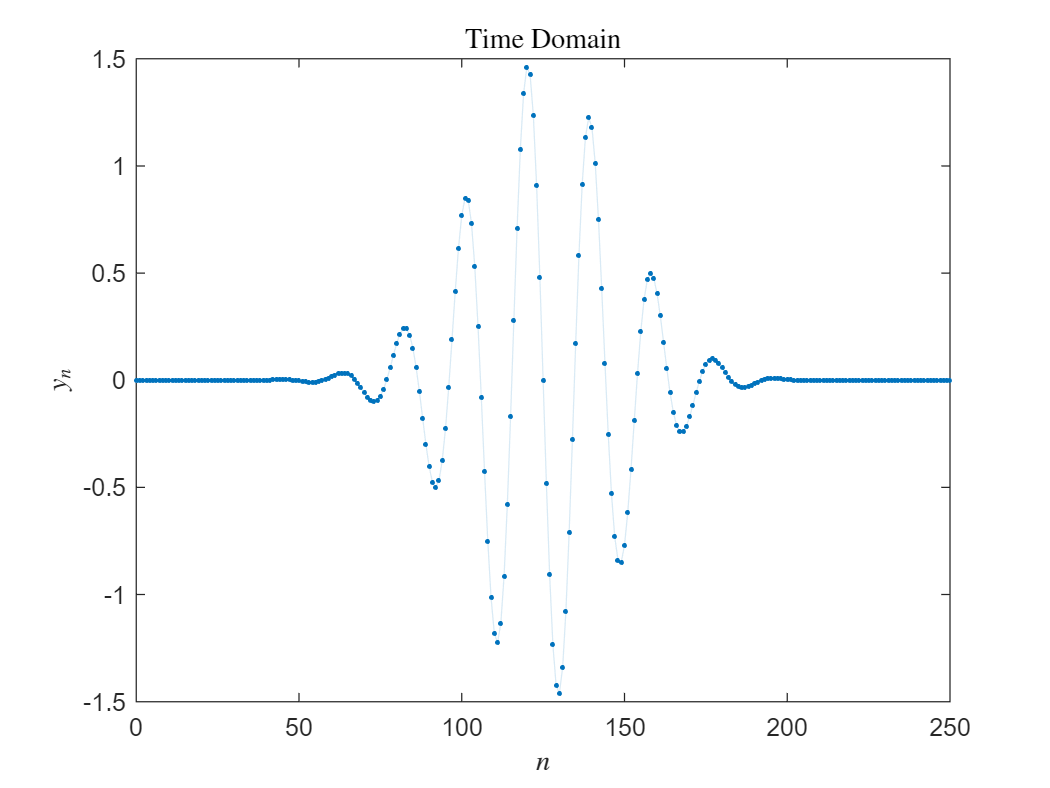

N = 250; % Number of points to use
y = createGaussSineData(N); % Helper function that creates the data
plotGaussSineData(y) % Helper function that plots the data

**Task 2. **Run this section to compute the DFT using [`fft`](https://www.mathworks.com/help/matlab/ref/fft.html) and plot the result.

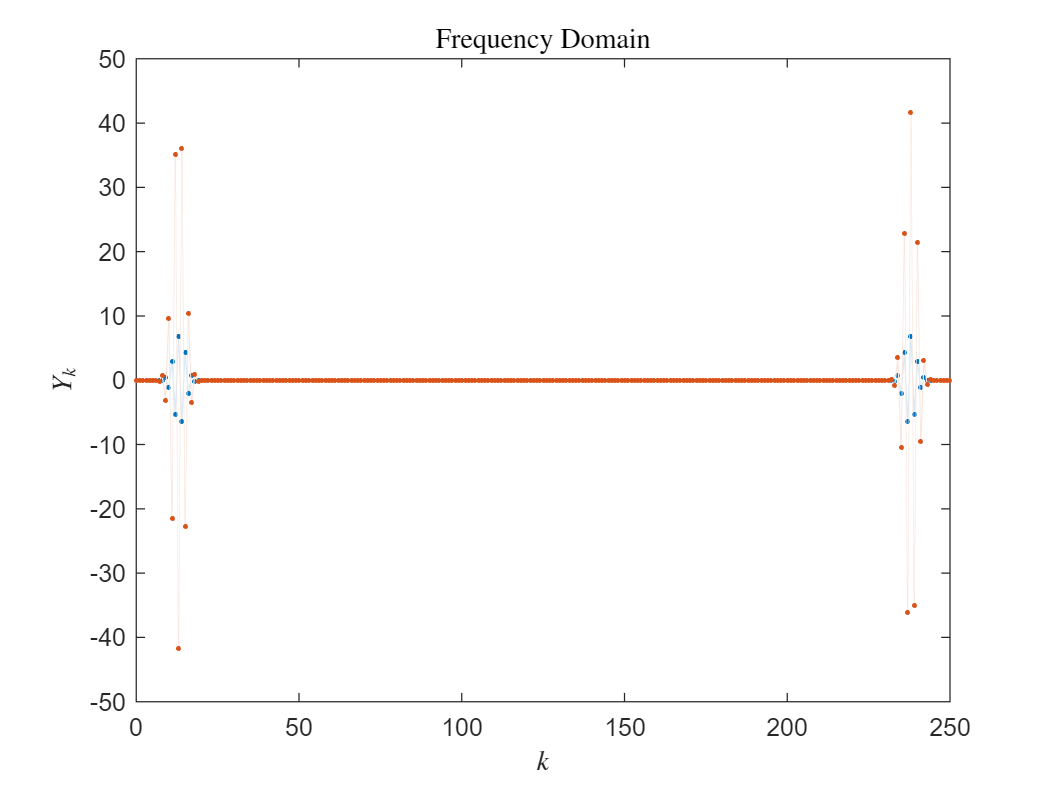

Y = fft(y);
plotGaussSineTransform(Y)

**Task 3.** Run this section to plot the analytic Fourier transform for the continuous function.

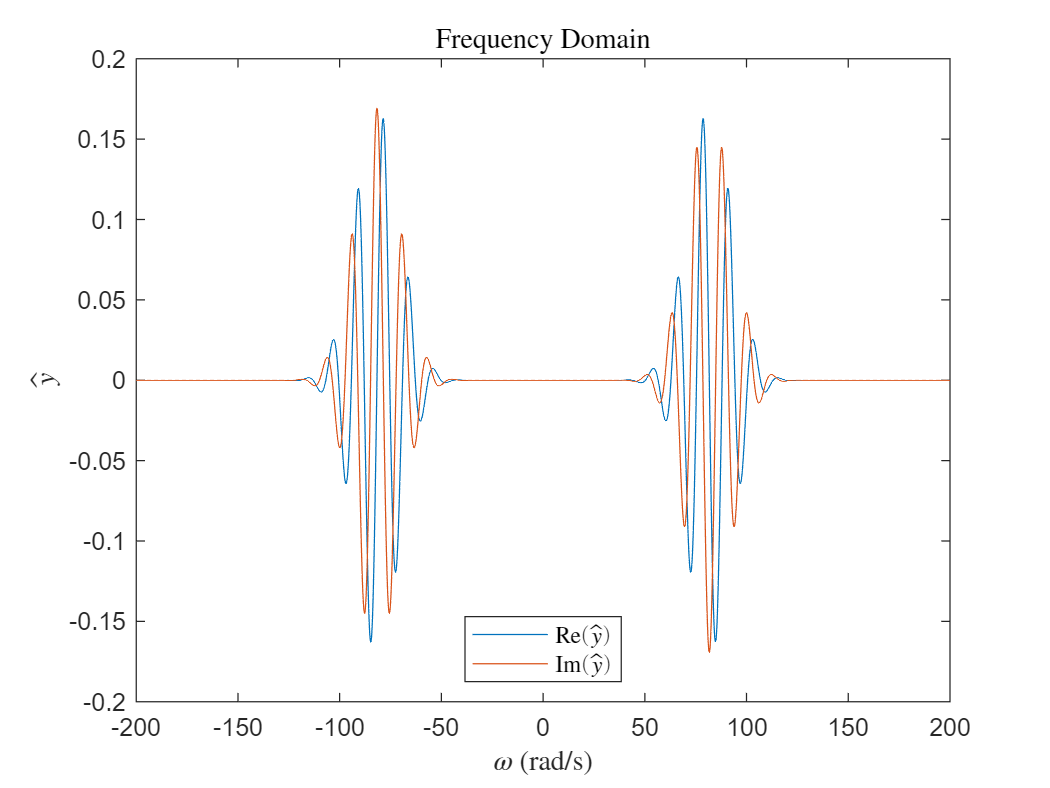

plotFourierTransform % Helper function that plots the Fourier transform

**  Reflect.** 

- How is the DFT (shown in **Task 2**) *similar* to the Fourier transform (shown in **Task 3**)?

- How is the DFT *different* from the Fourier transform?

- Try *increasing* the number of data points and rerunning the first two sections. How does the DFT change?

- Try *decreasing* the number of data points and rerunning the first two sections. How does the DFT change?

### Relating the DFT to the Fourier Transform

You probably noticed that the DFT looks similar to but not the same as the analytic Fourier transform of the Gaussian-modulated sinusoid. Unfortunately, the result of the DFT is not just a sampled version of the Fourier transform. In this section, you will learn the techniques required to relate the DFT to the Fourier transform. The explanation for *why *these changes are required will be given in another lesson.

 **Exercise.**  In this exercise, you will compute the DFT using the FFT algorithm and relate the result to the analytic Fourier transform.

**Task 1.** First, create and plot the data points (stored in the vector `y)` by running this section.

N = 250; % Number of points to use
[y,Fs] = createGaussSineData(N); % Helper function that creates the data
plotGaussSineData(y) % Helper function that plots the data

**Task 2. **Use the [`fft`](https://www.mathworks.com/help/matlab/ref/fft.html) function to compute the DFT of `y` and store the result in Y. 

% Write your code here
Y = fft(y);

**Task 3.**

**Task 3. **The 

**Task 4. **Plot the real and imaginary components of `Y`. To extract the real and imaginary components, use the [`real`](https://www.mathworks.com/help/matlab/ref/real.html) and [`imag`](https://www.mathworks.com/help/matlab/ref/imag.html) function. Use [`hold`](https://www.mathworks.com/help/matlab/ref/hold.html) commands to continue plotting on the same axes.

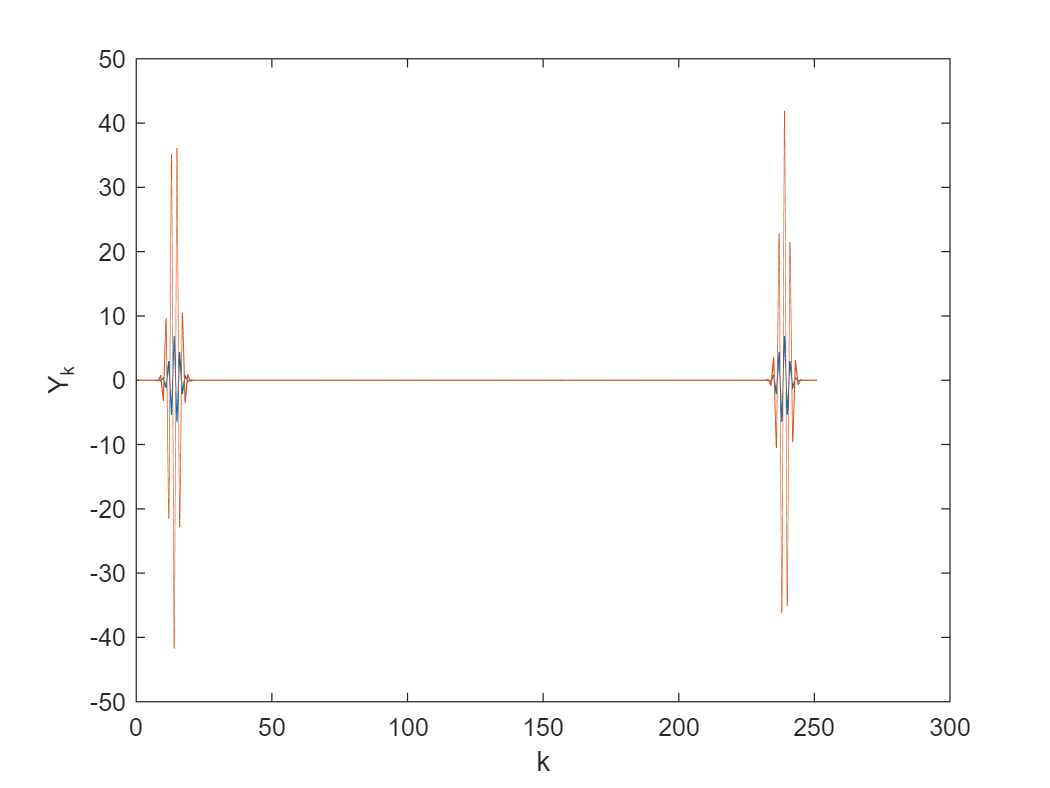

% Write your code here
plot(real(Y))
hold on
plot(imag(Y))
hold off
xlabel("k")
ylabel("Y_k")

If correct, your result should be identical to the plot from the previous example.

## Comparing the DFT to the Fourier Transform

You probably noticed that the DFT looks similar to what you'd expect from the Fourier transform of the Gaussian-modulated sinusoid. There's a high frequency peak, which you'd expect to be 110 Hz (the carrier frequency). However, the axes aren't labeled in terms of the frequency $f$ or angular frequency $\omega$, so it's difficult to know for sure. If you zoom in, you can also see that there's what appears to be a Gaussian-modulated sinusoid with real and complex parts, but it appears coarse. Also, notice that the vertical axes are off by 100x.

In order to better understand what is computed by the DFT, it's helpful to look at the analytic Fourier transform for the same function.

**Task. **Run this section to show the analytic plot. 

plotFourierTransform
 

**  Reflect.** 

- Which peaks in the DFT correspond to the peaks of the Fourier transform?

- Zoom in on one of the peaks in the frequency domain (the plot of $\hat{y}$). How does the Fourier transform compare to the  DFT?

To understand the differences, let's compare the DFT and Fourier transform definitions. The DFT:


$$Y_k = \sum_{n = 0}^{N-1} y_n e^{- \frac{ 2 \pi i k n }{N }$$


The Fourier transform:


$$\hat{y}(\omega) = \int_{-\infty}^\infty y(t) e^{-i\omega t} \ dt$$


It's immediately clear that the DFT sum approximates the integral in the analytic Fourier transform. It's also evident that the factors in the DFT are the discrete analogs of the factors in the Fourier transform integrand: $ y_n \leftrightarrow y(t)$ and $e^{- \frac{ 2 \pi i k n }{N }} \leftrightarrow  e^{-i\omega t} \ dt$. 

However, there are two important differences:

- Because the integral is taken with respect to time ($dt$), the scale of $\hat{y}$ will depend on the time scale, while $Y_k$ will not.

- The complex exponential is given in terms of discrete indices: $k$ and $n$, rather than continuous variables, $\omega$ and $t$.

 **Example.** In the example, the DFT will be related to the Fourier transform using the Gaussian-modulated sinusoid.

**Task**. Run this section to compute the DFT using the [`fft`](https://www.mathworks.com/help/matlab/ref/fft.html) function.

Fs = 5e3; % Audio sample rate
t = 0:1/Fs:(2-1/Fs); % 2 second time variable
y = sin(2*pi*110*t).*exp(-5*(t-1).^2); % Sampled audio signal (Gaussian-modulated sinusoid)
Y = fft(y);

The Fourier transform is scaled (in amplitude) by $dt$. The discrete analog of $dt$ is the time step $\Delta t$ in the sampled signal. The time step $\Delta t = 1/ f_s$, where $f_s$  is the sampling frequency. This implies that, to rescale the output $Y$ to match $\hat{y}$, you can multiply by `1/Fs`.

**Task. **Run this section to rescale `Y` and plot the result. Compare the vertical axis scale to result of the analytic Fourier transform.

N = length(Y);
k = 0:(N-1);
Yrescaled = 1/Fs*Y;
realImagPlot(k,Yrescaled,"$k$","$\frac{1}{f_s}Y_k$"); % Helper function that creates the plot

You can also use the sample rate `Fs` to relate the discrete indices $k$ and $n$ to the continuous variables $\omega$ and $t$. Equating these terms in the exponentials of each definition:


$$  \frac{2 \pi kn}{N} = t \omega$$


The discretized version of $t$ is $n \Delta t  = n / f_s$, so


$$\frac{2 \pi kn}{N} = \frac{n}{f_s} \omega$$


So the discrete frequencies used by the DFT are


$$\omega_k = \frac{ 2 \pi k f_s}{   N}$$


**Task. **Run this section to plot the DFT result against the angular frequencies $\omega_k$.

omega = 2*pi*k*Fs/N;
realImagPlot(omega,Yrescaled,"$\omega$","$\frac{1}{f_s}Y_k$"); % Helper function that creates the plot

Compare the angular frequencies of the DFT to those of the Fourier transform. Are the peaks in the same location? You can identify the locations of the peaks by clicking on the graph to create a tooltip. 

You should notice that the **first **peak of the DFT matches the **second** peak of the Fourier transform. Why does this happen? In the DFT definition:


$$Y_k = \sum_{n = 0}^{N-1} y_n e^{- \frac{ 2 \pi i k n }{N }$$


Only positive frequencies are computed. This means that the first value of the DFT, $Y_0$, corresponds to $\omega = 0$. Compare that to the Fourier transform, which is plotting both negative and positive frequencies.

So, how do you relate the two? It turns out that the discrete Fourier transform copies the negative frequency peak to high frequencies. This is one of the greatest points of confusion for the DFT, and it will be discussed in more detail later. In order to adjust the DFT so it better matches the Fourier transform, you shift the second half of the computed points to negative frequencies.

**Task. **Run this section to move the high frequency copy to negative frequencies and plot the result. Note that you could also use [`fftshift`](https://www.mathworks.com/help/matlab/ref/fftshift.html) to shift the values of $\{ Y_k \}$ (the function exists for this purpose).

% Shift the Y-values
Yshift = [Yrescaled(N/2+1:N),Yrescaled(1:N/2)];
% Shift omega
omegaShift = 2*pi*Fs/N*(-N/2+1:N/2);

realImagPlot(omegaShift,Yshift,"$\omega$","$\frac{1}{f_s}Y_k$"); % Helper function that creates the plot
xlim([-1000,1000])


**Helper Functions**

function plotFourierTransform

    % Parameters
    A = 1.5; % Amplitude
    f0 = 13; % Carrier frequency (Hz)
    c = 0.09; % Gaussian "width"
    t0 = 0.5; % Center position (s)
    omega0 = f0*2*pi; % Angular frequency (rad/s)

    % Plot parameters
    omegaLims = [-200,200];

    % Compute transform
    omega = linspace(omegaLims(1),omegaLims(2),5e3);
    ghat = -A*sqrt(pi/2)*1i*c.*(exp(-0.5*(omega-omega0).*(c^2*omega-c^2*omega0+2*t0*1i)) - ...
        exp(-0.5*(omega+omega0).*(c^2*omega+c^2*omega0+2*t0*1i)));

    figure
    plot(omega,real(ghat))
    hold on
    plot(omega,imag(ghat))
    hold off
    xlim([omega(1),omega(end)])
    xlabel("$\omega$ (rad/s)","Interpreter","latex")
    ylabel("$\hat{y}$","Interpreter","latex")
    legend("Re$(\hat{y})$","Im$(\hat{y})$","Interpreter","latex","Location","south");
    title("Frequency Domain","Interpreter","latex")

end

function realImagPlot(x,y,xLabel,yLabel)
    figure
    plot(x,real(y))
    hold on
    plot(x,imag(y))
    hold off
    xlabel(xLabel,"Interpreter","latex")
    ylabel(yLabel,"Interpreter","latex")
end

function [y,Fs] = createGaussSineData(N)
    % Gaussian-modulated sine data
    A = 1.5; % Amplitude
    f0 = 13; % Carrier frequency (Hz)
    c = 0.09; % Gaussian "width"
    t0 = 0.5; % Center position (s)
    omega0 = f0*2*pi; % Angular frequency (rad/s)

    % Discretize
    Fs = N; % Sample rate (1/s)
    tmax = 1;
    tmin = 0;
    N = round(Fs*(tmax-tmin));
    t = (0:1/Fs:N/Fs) + tmin;
    y = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));
end

function plotGaussSineData(y)
    n = 0:(numel(y)-1);
    colors = lines(2);
    washed = 0.15*lines(2) + 0.85*[1 1 1];

    figure
    plot(n,y,"Color",washed(1,:))
    hold on
    plot(n,y,'.',"Color",colors(1,:))
    hold off
    xlabel("$n$","Interpreter","latex")
    ylabel("$y_n$","Interpreter","latex")
    title("Time Domain","Interpreter","latex")
    xlim(n([1,end]))
end

function plotGaussSineTransform(Y)
    k = 0:(numel(Y)-1);
    colors = lines(2);
    washed = 0.15*lines(2) + 0.85*[1 1 1];

    figure
    plot(k,real(Y),'-',"Color",washed(1,:))
    hold on
    plot(k,real(Y),'.',"Color",colors(1,:))
    plot(k,imag(Y),'-',"Color",washed(2,:))
    plot(k,imag(Y),'.',"Color",colors(2,:))
    hold off
    xlabel("$k$","Interpreter","latex")
    ylabel("$Y_k$","Interpreter","latex")
    title("Frequency Domain","Interpreter","latex")
    xlim(k([1,end]))
end